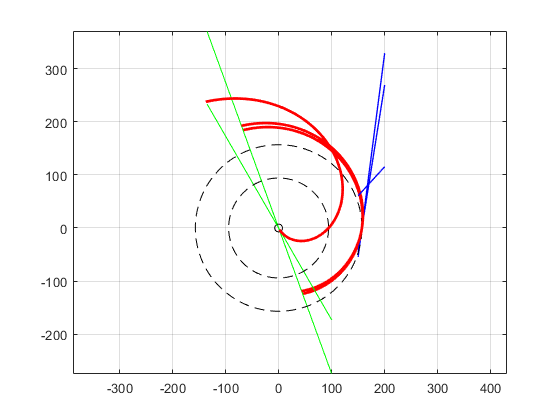

a = 200;
b = 300;
s = 200;
m = a/b;

rMin = 0.3 * (pi/4) * (a + s);
rMax = 0.7 * (pi/4) * (b + s);

thetaMin = 0;
thetaMax = deg2rad(120);


xaxis = -135:1:100;
xxaxis = 150:1:200;

%Initial orientation of shell
initialAxis = tan(thetaMax)*xaxis;
normalAxis = tan(deg2rad(30))*xaxis;

c2 = (rMax - rMin)/thetaMax;
c1 = rMin;

contactTangent = (c1/c2) .* (xxaxis - rMin);

alpha = 0:0.01*pi:2*pi;
theta = (thetaMax-pi):0.01*pi:thetaMax;
r = c1 + c2.*theta;

x = r.*cos(theta);
y = r.*sin(theta);

dxdtheta = -c1.*sin(theta) + c2.*(cos(theta) - theta.*sin(theta));
dydtheta = c1.*cos(theta) + c2.*(sin(theta) + theta.*cos(theta));
tangent = dydtheta./dxdtheta;

plot(0, 0, 'k-o'); hold on;
plot(xaxis, initialAxis, 'g-'); hold on;
%plot(xaxis, normalAxis); hold on;
plot(xxaxis, contactTangent, 'b-', 'LineWidth', 1); hold on;
plot(rMin.*cos(alpha), rMin.*sin(alpha), 'k--'); hold on;
plot(x, y, 'r-','LineWidth', 2); hold on;

axis equal
grid on